% Rocky_5_closed_loop_poles.m
%
% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% No motor model (M =1). With motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki, Kp, Ji, Jp, Ci to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. In this case (5th order), the control constants can be found exactly 
%
% 5) Plot impulse response to see closed-loop behavior. 
%
% based on code by SG. last modified 3/8/22 CL

clear all; 
close all;

syms s a b l g Kp Ki Jp Ji Ci   % define symbolic variables

Hvtheta = -s/l/(s^2-g/l);       % TF from velocity to angle of pendulum

K = Kp + Ki/s;                  % TF of the PI angle controller
M = a*b/(s+a);                  % TF of motor (1st order model) 
% M = 1;                        % TF without motor
%
J = Jp + Ji/s + Ci/s^2;         % TF of controller around motor-combined PI of x and v
Mfb = M/(1+M*J);                % Black's formula to get tf for motor with PI feedback control 

% closed loop transfer function from disturbance d(t)totheta(t)
% Hcloop = 1/(1-Hvtheta*M*K)    % use this for no motor feedback
% with motor feedback
Hcloop = 1/(1-Hvtheta*Mfb*K);    % use this for motor with feedback

% Substitute parameters and solve system parameters
g = 9.81;
l = .4992;  %effective length 

tau_motor_L = 0.0573; 
tau_motor_R = 0.0562; 
alpha_motor_L = 1/tau_motor_L;
alpha_motor_R = 1/tau_motor_R;
beta_motor_L = 0.0026;
beta_motor_R = 0.0025;

a = (alpha_motor_R+alpha_motor_L)/2

a = 17.6228

b = (beta_motor_R+beta_motor_L)/2

b = 0.0026

    

Hcloop_sub = subs(Hcloop); % sub parameter values into Hcloop

% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc.
p1 = -4

p1 = -4

p2 = -5

p2 = -5

p3 = -3 + 1i

p3 = -3.0000 + 1.0000i

p4 = -3 - 1i

p4 = -3.0000 - 1.0000i

p5 = -6

p5 = -6


% check polynomial-expand to fifth order 
tgt_char_poly = (s-p1)*(s-p2)*(s-p3)*(s-p4)*(s-p5);
exp_tgt_char_poly = expand(tgt_char_poly);

% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub);

% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s);

% divide though the coefficient of the highest power term
coeffs_denom = coeffs(d, s)/(coeffs_denom(end));
% num_coeff_denom = length(coeffs_denom)

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s);
% num_coeff_tgt = length(coeffs_tgt)

% for check. reorder the coefficients to match the denomimator polynomial
for ii = 1:length(coeffs_denom)
    reord_coeffs_tgt(ii) = coeffs_tgt(length(coeffs_tgt) + 1 - ii);
end
% check roots of target polynomial-should be same as selected poles
roots_target = vpa(roots(reord_coeffs_tgt),4);

% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:5) == coeffs_tgt(1:5), Jp, Ji,  Kp, Ki, Ci);

% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 2.9765e+03

Ki = double(solutions.Ki)

Ki = 1.3194e+04

Ji = double(solutions.Ji)

Ji = -1.6533e+03

Jp = double(solutions.Jp)

Jp = 75.1522

Ci = double(solutions.Ci)

Ci = -1.3589e+03


%write out denominator polynomial 
aaa = vpa(subs(coeffs_denom),4);

% reorder coefficients for the check polynomial 
for ii = 1:length(coeffs_denom)
    chk_coeffs_denom(ii) = coeffs_denom(length(coeffs_denom) + 1 - ii);
end

% check poles should be same as chosen input poles 
check_closed_loop_poles = vpa (roots(subs(chk_coeffs_denom)), 4)

$$check\_closed\_loop\_poles = \left(\begin{array}{c} -6.0\\ -5.0\\ -4.0\\ -3.0-1.0\,\mathrm{i}\\ -3.0+1.0\,\mathrm{i} \end{array}\right)$$


% Plot impulse and step responses of closed-loop system
TFstring = char(subs(Hcloop));
% Define 's' as transfer function variable
s = tf('s');
% Evaluate the expression
eval(['TFH = ',TFstring]);

TFH =
 
  3.505e72 s^8 + 1.354e74 s^7 + 9.678e74 s^6 - 7.463e75 s^5 - 2.414e76 s^4 + 9.438e76 s^3 + 7.412e76 s^2
  ------------------------------------------------------------------------------------------------------
  3.505e72 s^8 + 1.354e74 s^7 + 1.907e75 s^6 + 1.325e76 s^5 + 4.922e76 s^4 + 9.438e76 s^3 + 7.412e76 s^2
 
Continuous-time transfer function.


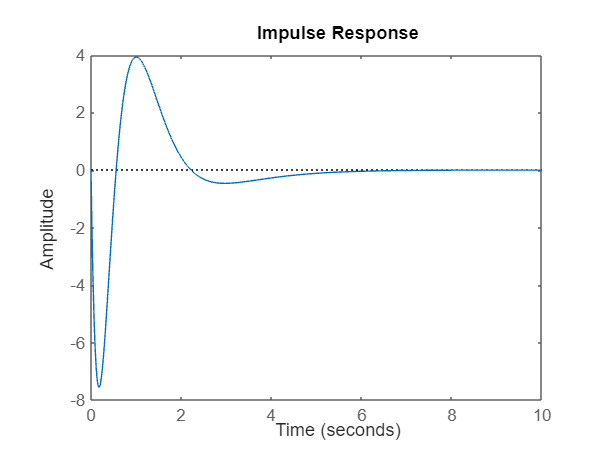

figure
impulse(TFH);   %plot the impulse reponse
axis([0 10 -8 4])

% figure(2)
% step(TFH)       %plot the step response